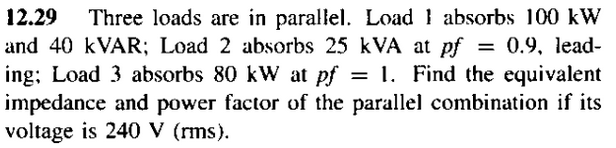

sabemos que cada carga al estar en paralelo con la fuente, tienen unca tension de 240V rms

clc, clear, close all
format short g

vf = 240;

S1 = 100e3 + 40e3*j; %potencia aparente [VA]

s2 = 25e3; %potencia aparente [VA]
fp2 = 0.9; %adelanto capacitiva

p3 = 80e3; %carga resistiva


primero transofrmamos todo a potencia compleja

p2 = s2*fp2;
q2 = p2*tan(-acos(fp2));

S2 = p2 + q2*j

S2 =         22500 -      10897i


S3 = p3;

ya que tenemos las potencias complejas en cada carga, podemos calcular la corriente en cada una:

I1 = conj(S1/(vf))

I1 =        416.67 -     166.67i


I2 = conj(S2/(vf))

I2 =         93.75 +     45.405i


I3 = conj(S3/(vf))

I3 =        333.33


teniendo las correintes por ley de ohm podemos calcular la impedancia de cada una:

z1 = vf/I1

z1 =       0.49655 +    0.19862i


z2 = vf/I2

z2 =        2.0736 -     1.0043i


z3 = vf/I3

z3 =          0.72


sabemos que la impedancias estan en paralelo, asi hallamos la impedancia equivalente

zeq = (1/((1/(z1))+(1/(z2))+(1/(z3))))*1000

zeq =        278.69 +     40.052i
